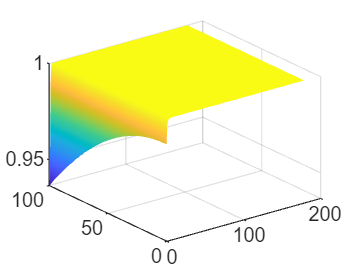

clear; clc;
mFile = '..\mask2m_16_16.mat';
load(mFile); % mask2m 304x304x361

% Get the dimensions of the data
[h, w, c] = size(mask2m);

% Reshape the data into a 2D matrix
x = reshape(mask2m, h * w, c);

% Calculate the FFT 
fftx = fft(x, [], 2);

% Calculate the Energy Spectrum of fftx
fftEspec = abs(fftx).^2;

% Get the indices of the most important frequencies
[Espec, fftEspecOrder] = sort(fftEspec(:,1:180), 2, 'descend');
Espec = cumsum(Espec, 2)./(sum(Espec, 2)*ones([1 180]));

% Visualization
surf(Espec(1:100,:)); shading interp



% Number of frequencies to find
numFrequencies = 10; % You can change this to 5 or 10 based on your requirement

% Call the function with the calculated values
highestFreqs = find_highest_frequencies_within_99_percent(Espec, fftEspec, fftEspecOrder, numFrequencies);
disp(['Within the 99% energy coverage, the highest frequencies are: ', num2str(highestFreqs)]);

Within the 99% energy coverage, the highest frequencies are: 1   2   3   4   3   6   6   9  16   6



% Save the frequencies to a CSV file
csvwrite('highest_frequencies.csv', highestFreqs);



% Modified function to find the highest 5 or 10 frequencies within 99% energy coverage

function [highestFreqs] = find_highest_frequencies_within_99_percent(Espec, fftEspec, fftEspecOrder, numFrequencies)
    highestFreqs = zeros(1, numFrequencies);
    energyValues = zeros(1, numFrequencies);
    
    [numPositions, ~] = size(Espec); % Get the number of positions
    
    for i = 1:numPositions
        index99 = find(Espec(i,:) >= 0.99, 1, 'first');
        if isempty(index99)
            continue;
        end
        
        [sortedEnergies, sortedIndices] = sort(fftEspec(i, 1:index99), 'descend');
        currentFreqs = fftEspecOrder(i, sortedIndices(1:min(numFrequencies, length(sortedIndices))));
        
        for j = 1:min(numFrequencies, length(currentFreqs))
            if sortedEnergies(j) > energyValues(j)
                highestFreqs(j) = currentFreqs(j);
                energyValues(j) = sortedEnergies(j);
            end
        end
    end
end

